# This exercise is to forecast volatility via different methods, campared with actual volatilities measured by high-frequency realised volatility

clc,clear
addpath("data_Files/")
addpath("m_Files_ClusterPartition/")
addpath("m_Files_GARCHfamily/")
addpath("m_Files_Color/colormap/");

load("dax_rv.mat")
load("ftse_rv.mat")
load("nikkie_rv.mat")
load("sp_rv.mat")
dax=readtable("DAX daily.xlsx");
dax(:,3:end)=[];dax.Properties.VariableNames=["Date","Price"]

dax = 8443×2 table
       Date        Price 
    ___________    ______

    02-Jan-1989    1335.1
    03-Jan-1989    1362.3
    04-Jan-1989    1373.2
    05-Jan-1989    1376.6
    06-Jan-1989      1361
    09-Jan-1989    1372.4
    10-Jan-1989    1353.5
    11-Jan-1989    1354.4
    12-Jan-1989    1361.9
    13-Jan-1989      1358
    16-Jan-1989    1350.6
    17-Jan-1989    1344.1
    18-Jan-1989    1316.7
    19-Jan-1989    1340.1
    20-Jan-1989    1330.1
    23-Jan-1989    1318.3


ftse=readtable("FTSE daily.xlsx");
ftse(:,3:end)=[];ftse.Properties.VariableNames=["Date","Price"]

ftse = 8437×2 table
       Date        Price 
    ___________    ______

    03-Jan-1989    1783.2
    04-Jan-1989    1785.7
    05-Jan-1989    1801.9
    06-Jan-1989    1798.1
    09-Jan-1989    1826.5
    10-Jan-1989    1828.6
    11-Jan-1989      1833
    12-Jan-1989    1837.5
    13-Jan-1989    1853.5
    16-Jan-1989    1866.6
    17-Jan-1989    1868.9
    18-Jan-1989    1871.7
    19-Jan-1989    1911.5
    20-Jan-1989    1908.7
    23-Jan-1989    1917.6
    24-Jan-1989    1922.7


nikkie=readtable("NIKKIE daily.xlsx");
nikkie(:,3:end)=[];nikkie.Properties.VariableNames=["Date","Price"]

nikkie = 8198×2 table
       Date        Price
    ___________    _____

    04-Jan-1989    30166
    05-Jan-1989    30260
    06-Jan-1989    30226
    09-Jan-1989    30223
    10-Jan-1989    30683
    11-Jan-1989    31010
    12-Jan-1989    31141
    13-Jan-1989    31148
    17-Jan-1989    31299
    18-Jan-1989    31244
    19-Jan-1989    31367
    20-Jan-1989    31275
    23-Jan-1989    31199
    24-Jan-1989    31350
    25-Jan-1989    31567
    26-Jan-1989    31580


sp=readtable("S&P500 daily.xlsx");
sp(:,3:end)=[];sp.Properties.VariableNames=["Date","Price"]

sp = 8413×2 table
       Date        Price 
    ___________    ______

    03-Jan-1989    277.71
    04-Jan-1989    275.41
    05-Jan-1989    279.44
    06-Jan-1989    279.99
    09-Jan-1989    280.68
    10-Jan-1989    280.96
    11-Jan-1989    280.35
    12-Jan-1989    282.01
    13-Jan-1989    283.17
    16-Jan-1989    283.86
    17-Jan-1989    284.12
    18-Jan-1989    283.55
    19-Jan-1989    286.54
    20-Jan-1989    286.89
    23-Jan-1989    287.85
    24-Jan-1989    284.49


## SP500

Timeline=sp.Date;
Time_outsample=sp_rv_table.date;
logret=[0;price2ret(sp.Price)];
rv=sp_rv_table.rv;
Index='sp';

Set empty matrices

index=(Timeline>=Time_outsample(1) & Timeline<=Time_outsample(end));
if sum(index)~=numel(Time_outsample)
    warning("Dates of daily prices and realised volatilities do not match.")
end

Ret_outsample=logret(index);
OutsampleStart=find(Timeline==Time_outsample(1));
n=numel(Time_outsample);

v_residuals=Ret_outsample.^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vol_persis=zeros(n,1);

Rolling windows forecast

for t=1:n
    ret=logret(OutsampleStart+t-1-252:OutsampleStart+t-1-1,:);

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(t)=forecast(EstMdl,1,ret);
    vol_persis(t)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    % CPGARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,1);
    K = OptimalClusterNumber(v_GARCH,LB);
    if K==numel(v_GARCH)
        K=K-1;
    end
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    vf_CPGARCH(t)=v_CPGARCH(end);

    % CPGARCH iteration
    v_CPGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGARCH);
    vf_CPGARCHiteration(t)=v_CPGARCHiteration(end);

    % EGARCH
    Mdl=egarch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(t)= forecast(EstMdl,1,ret);
    [LB,J,~]=Fisher_div_sqr(v_EGARCH,1);
    K = OptimalClusterNumber(v_EGARCH,LB);
    if K==numel(v_EGARCH)
        K=K-1;
    end
    [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    vf_CPEGARCH(t)=v_CPEGARCH(end);
    v_CPEGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPEGARCH);
    vf_CPEGARCHiteration(t)=v_CPEGARCHiteration(end);

    % GJR-GARCH
    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    vf_GJRGARCH(t)= forecast(EstMdl,1,ret);
    v_GJRGARCH = infer(EstMdl,ret);
    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,1);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    if K==numel(v_GJRGARCH)
        K=K-1;
    end
    [v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    vf_CPGJRGARCH(t)=v_CPGJRGARCH(end);
    v_CPGJRGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGJRGARCH);
    vf_CPGJRGARCHiteration(t)=v_CPGJRGARCHiteration(end);

    % RSGARCH
    addpath("m_Files_swgarch")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_RSGARCH(t)=datafcst.vH;
    rmpath("m_Files_swgarch")
end

## Results: 9 graphs with "log returns", "residual squares", "GARCH conditional variance", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "GJRGARCH forecast" and "RSGARCH forecast"

figure;
subplot(5,2,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,2,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,2,3);
v_GARCH=estimateGARCH(Ret_outsample,garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN));
line(Time_outsample,v_GARCH);
ylabel('GARCH Con.Var.');dateaxis("x",12);
subplot(5,2,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH forecast');dateaxis("x",12);
subplot(5,2,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH forecast');dateaxis("x",12);
subplot(5,2,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite. ');dateaxis("x",12);
subplot(5,2,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,2,8);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,2,9);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: 13 graphs with "log returns", "residual squares", "realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

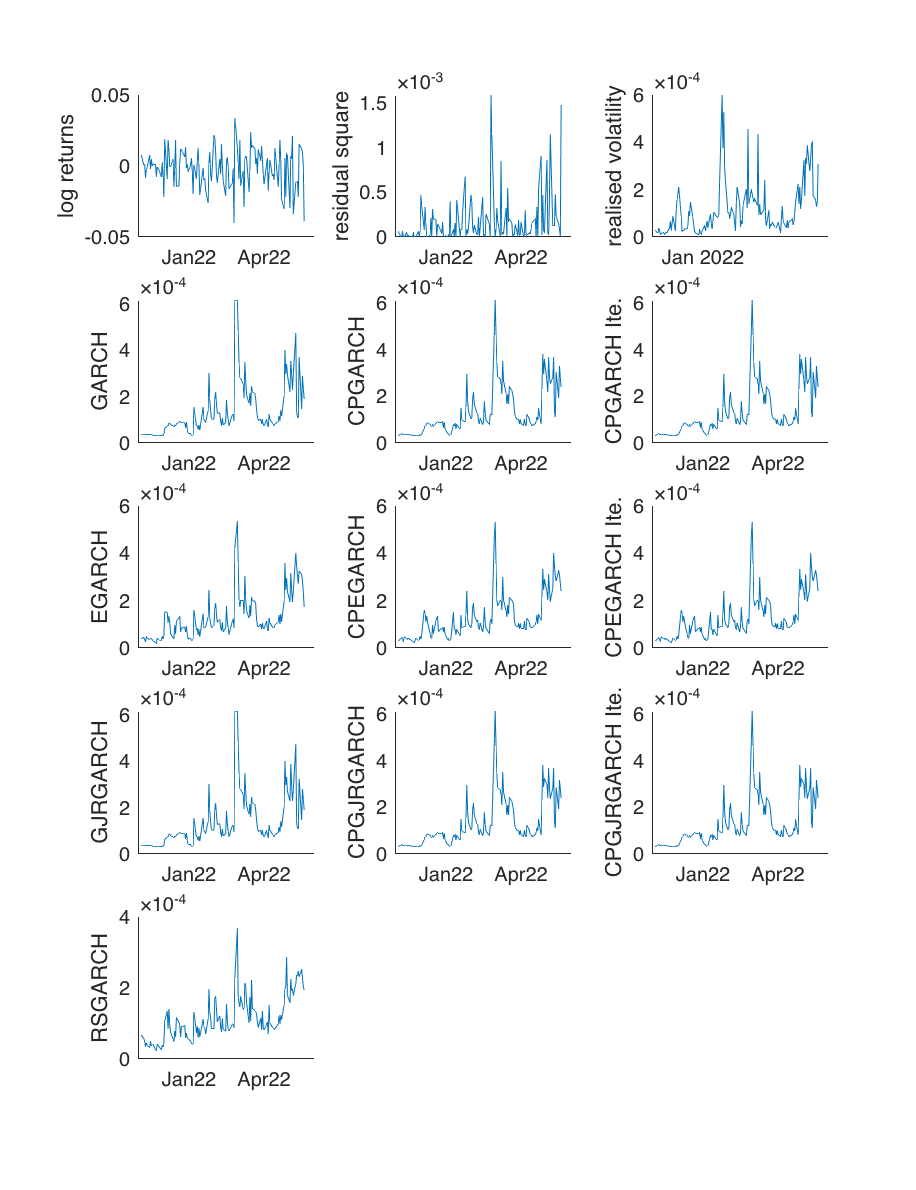

figure;
subplot(5,3,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,3,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,3,3);
line(Time_outsample,rv);
ylabel('realised volatility')
subplot(5,3,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH');dateaxis("x",12);
subplot(5,3,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH');dateaxis("x",12);
subplot(5,3,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite.');dateaxis("x",12);
subplot(5,3,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,3,8);
line(Time_outsample,vf_CPEGARCH);
ylabel('CPEGARCH');dateaxis("x",12);
subplot(5,3,9);
line(Time_outsample,vf_CPEGARCHiteration);
ylabel('CPEGARCH Ite.');dateaxis("x",12);
subplot(5,3,10);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,3,11);
line(Time_outsample,vf_CPGJRGARCH);
ylabel('CPGJRGARCH');dateaxis("x",12);
subplot(5,3,12);
line(Time_outsample,vf_CPGJRGARCHiteration);
ylabel('CPGJRGARCH Ite.');dateaxis("x",12);
subplot(5,3,13);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast" and "CPGARCH iteration forecast"

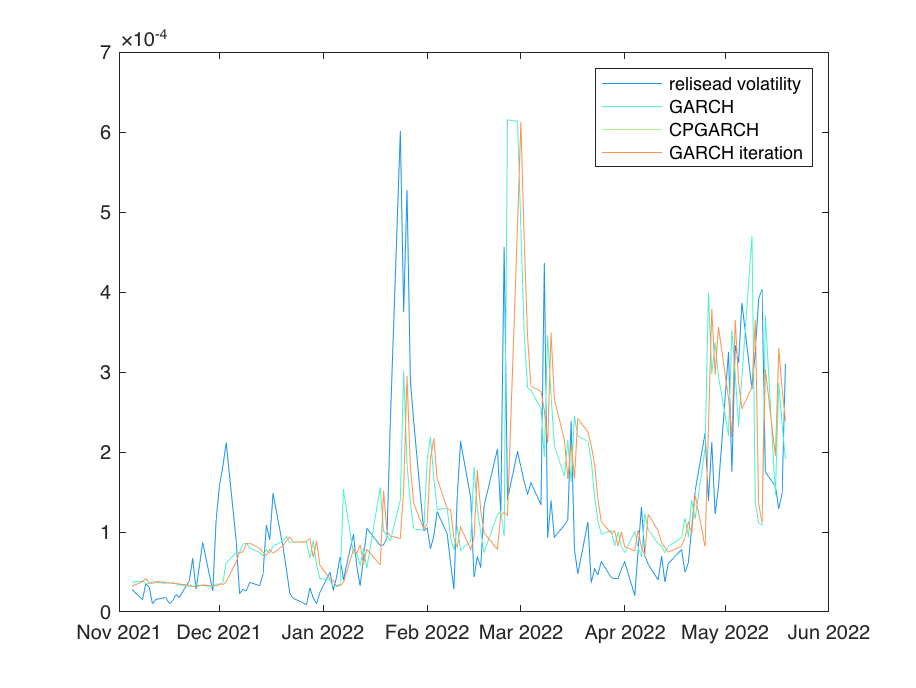

figure;
col=rainbow(4);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:))
plot(Time_outsample,vf_CPGARCH, "Color",col(3,:))
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:))
legend("relisead volatility","GARCH","CPGARCH","GARCH iteration");

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

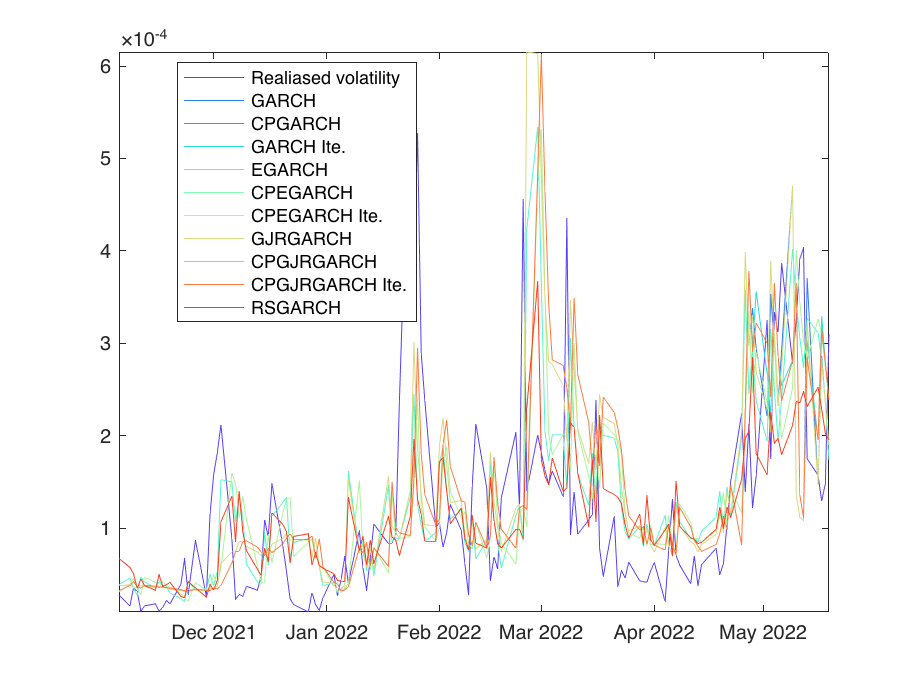

figure;
col=rainbow(11);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:));
plot(Time_outsample,vf_CPGARCH,"Color",col(3,:));
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:));
plot(Time_outsample,vf_EGARCH, "Color",col(5,:));
plot(Time_outsample,vf_CPEGARCH, "Color",col(6,:));
plot(Time_outsample,vf_CPEGARCHiteration, "Color",col(7,:));
plot(Time_outsample,vf_GJRGARCH, "Color",col(8,:));
plot(Time_outsample,vf_CPGJRGARCH,"Color",col(9,:));
plot(Time_outsample,vf_CPGJRGARCHiteration, "Color",col(10,:));
plot(Time_outsample,vf_RSGARCH, "Color",col(11,:));
legend("Realiased volatility","GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH","Location","best");

%legend("boxoff")

MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH               8.661e-05    0.00012658
    CPGARCH            8.0216e-05    0.00011714
    GARCH Ite.         8.0216e-05    0.00011714
    EGARCH             7.6602e-05    0.00011041
    CPEGARCH           7.5479e-05    0.00010702
    CPEGARCH Ite.      7.5479e-05    0.00010702
    GJRGARCH           8.6336e-05    0.00012626
    CPGJRGARCH         7.9724e-05    0.00011651
    CPGJRGARCH Ite.    7.9724e-05    0.00011651
    RSGARCH            6.8203e-05    0.00010012


## Test of actual forecast: 

## actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);
[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);
[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×3 table
                       low_bound    upper_bound      R2   
                       _________    ___________    _______

    GARCH               0.22503       0.54328      0.14635
    CPGARCH             0.30737       0.63213      0.19755
    GARCH Ite.          0.30737       0.63213      0.19755
    EGARCH              0.35448       0.72259      0.20117
    CPEGARCH            0.40006       0.75717        0.236
    CPEGARCH Ite.       0.40006       0.75717        0.236
    GJRGARCH            0.22515        0.5454      0.14551
    CPGJRGARCH          0.31261       0.63854      0.20034
    CPGJRGARCH Ite.     0.31261       0.63854      0.20034
    RSGARCH             0.57367        1.1176      0.22144


## Figure of volatility persistence

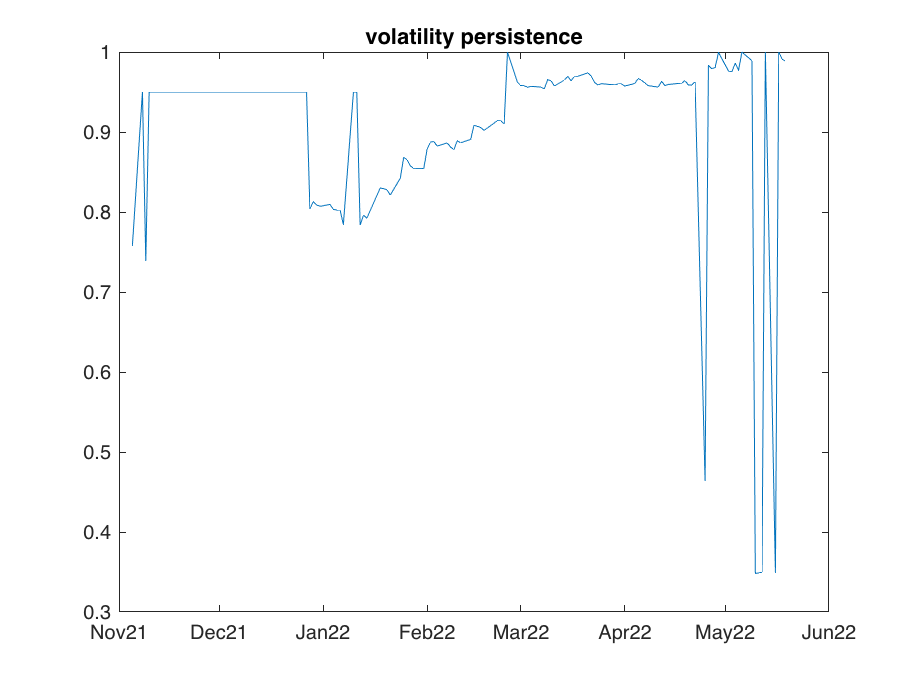

figure;
plot(Time_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_',Index,'_20220521'),"rv","vol_persis","Time_outsample","vf_GARCH", ...
    "vf_EGARCH","vf_GJRGARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_CPEGARCH","vf_CPEGARCHiteration","vf_CPGJRGARCH", ...
    "vf_CPGJRGARCHiteration","Ret_outsample");

## DAX30

Timeline=dax.Date;
Time_outsample=dax_rv_table.date;
logret=[0;price2ret(dax.Price)];
rv=dax_rv_table.rv;
Index='dax';

Set empty matrices

index=(Timeline>=Time_outsample(1) & Timeline<=Time_outsample(end));
if sum(index)~=numel(Time_outsample)
    warning("Dates of daily prices and realised volatilities do not match.")
end

Ret_outsample=logret(index);
OutsampleStart=find(Timeline==Time_outsample(1));
n=numel(Time_outsample);

v_residuals=Ret_outsample.^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vol_persis=zeros(n,1);

Rolling windows forecast

for t=1:n
    ret=logret(OutsampleStart+t-1-252:OutsampleStart+t-1-1,:);

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(t)=forecast(EstMdl,1,ret);
    vol_persis(t)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    % CPGARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,1);
    K = OptimalClusterNumber(v_GARCH,LB);
    if K==numel(v_GARCH)
        K=K-1;
    end
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    vf_CPGARCH(t)=v_CPGARCH(end);

    % CPGARCH iteration
    v_CPGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGARCH);
    vf_CPGARCHiteration(t)=v_CPGARCHiteration(end);

    % EGARCH
    Mdl=egarch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(t)= forecast(EstMdl,1,ret);
    [LB,J,~]=Fisher_div_sqr(v_EGARCH,1);
    K = OptimalClusterNumber(v_EGARCH,LB);
    if K==numel(v_EGARCH)
        K=K-1;
    end
    [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    vf_CPEGARCH(t)=v_CPEGARCH(end);
    v_CPEGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPEGARCH);
    vf_CPEGARCHiteration(t)=v_CPEGARCHiteration(end);

    % GJR-GARCH
    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    vf_GJRGARCH(t)= forecast(EstMdl,1,ret);
    v_GJRGARCH = infer(EstMdl,ret);
    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,1);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    if K==numel(v_GJRGARCH)
        K=K-1;
    end
    [v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    vf_CPGJRGARCH(t)=v_CPGJRGARCH(end);
    v_CPGJRGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGJRGARCH);
    vf_CPGJRGARCHiteration(t)=v_CPGJRGARCHiteration(end);

    % RSGARCH
    addpath("m_Files_swgarch")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_RSGARCH(t)=datafcst.vH;
    rmpath("m_Files_swgarch")
end

## Results: 9 graphs with "log returns", "residual squares", "GARCH conditional variance", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "GJRGARCH forecast" and "RSGARCH forecast"

figure;
subplot(5,2,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,2,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,2,3);
v_GARCH=estimateGARCH(Ret_outsample,garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN));
line(Time_outsample,v_GARCH);
ylabel('GARCH Con.Var.');dateaxis("x",12);
subplot(5,2,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH forecast');dateaxis("x",12);
subplot(5,2,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH forecast');dateaxis("x",12);
subplot(5,2,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite. ');dateaxis("x",12);
subplot(5,2,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,2,8);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,2,9);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: 13 graphs with "log returns", "residual squares", "realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

figure;
subplot(5,3,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,3,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,3,3);
line(Time_outsample,rv);
ylabel('realised volatility')
subplot(5,3,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH');dateaxis("x",12);
subplot(5,3,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH');dateaxis("x",12);
subplot(5,3,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite.');dateaxis("x",12);
subplot(5,3,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,3,8);
line(Time_outsample,vf_CPEGARCH);
ylabel('CPEGARCH');dateaxis("x",12);
subplot(5,3,9);
line(Time_outsample,vf_CPEGARCHiteration);
ylabel('CPEGARCH Ite.');dateaxis("x",12);
subplot(5,3,10);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,3,11);
line(Time_outsample,vf_CPGJRGARCH);
ylabel('CPGJRGARCH');dateaxis("x",12);
subplot(5,3,12);
line(Time_outsample,vf_CPGJRGARCHiteration);
ylabel('CPGJRGARCH Ite.');dateaxis("x",12);
subplot(5,3,13);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast" and "CPGARCH iteration forecast"

figure;
col=rainbow(4);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:))
plot(Time_outsample,vf_CPGARCH, "Color",col(3,:))
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:))
legend("relisead volatility","GARCH","CPGARCH","GARCH iteration");

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

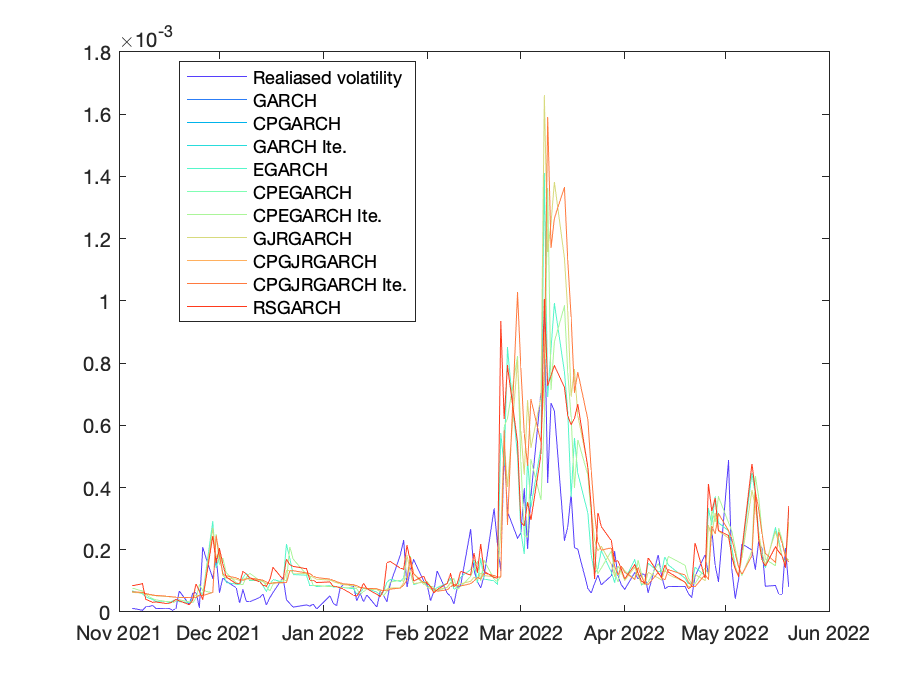

figure;
col=rainbow(11);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:));
plot(Time_outsample,vf_CPGARCH,"Color",col(3,:));
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:));
plot(Time_outsample,vf_EGARCH, "Color",col(5,:));
plot(Time_outsample,vf_CPEGARCH, "Color",col(6,:));
plot(Time_outsample,vf_CPEGARCHiteration, "Color",col(7,:));
plot(Time_outsample,vf_GJRGARCH, "Color",col(8,:));
plot(Time_outsample,vf_CPGJRGARCH,"Color",col(9,:));
plot(Time_outsample,vf_CPGJRGARCHiteration, "Color",col(10,:));
plot(Time_outsample,vf_RSGARCH, "Color",col(11,:));
legend("Realiased volatility","GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH","Location","best");

%legend("boxoff")

MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'});

ans = 10×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              0.00011204    0.00020115
    CPGARCH            0.00012029    0.00023107
    GARCH Ite.         0.00012029    0.00023107
    EGARCH             9.1209e-05    0.00014055
    CPEGARCH           9.5678e-05    0.00016532
    CPEGARCH Ite.      9.5678e-05    0.00016532
    GJRGARCH           0.00011204    0.00020115
    CPGJRGARCH         0.00012029    0.00023107
    CPGJRGARCH Ite.    0.00012029    0.00023107
    RSGARCH            9.9177e-05    0.00015443


## Test of actual forecast: 

## actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);
[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);
[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×3 table
                       low_bound    upper_bound      R2   
                       _________    ___________    _______

    GARCH                0.3686       0.47982      0.62771
    CPGARCH             0.28264       0.41535       0.4449
    GARCH Ite.          0.28264       0.41535       0.4449
    EGARCH              0.48865       0.63943      0.61857
    CPEGARCH            0.38348       0.56556      0.44045
    CPEGARCH Ite.       0.38348       0.56556      0.44045
    GJRGARCH             0.3686       0.47982      0.62771
    CPGJRGARCH          0.28264       0.41535       0.4449
    CPGJRGARCH Ite.     0.28264       0.41535       0.4449
    RSGARCH             0.44652        0.6237      0.51386


## Figure of volatility persistence

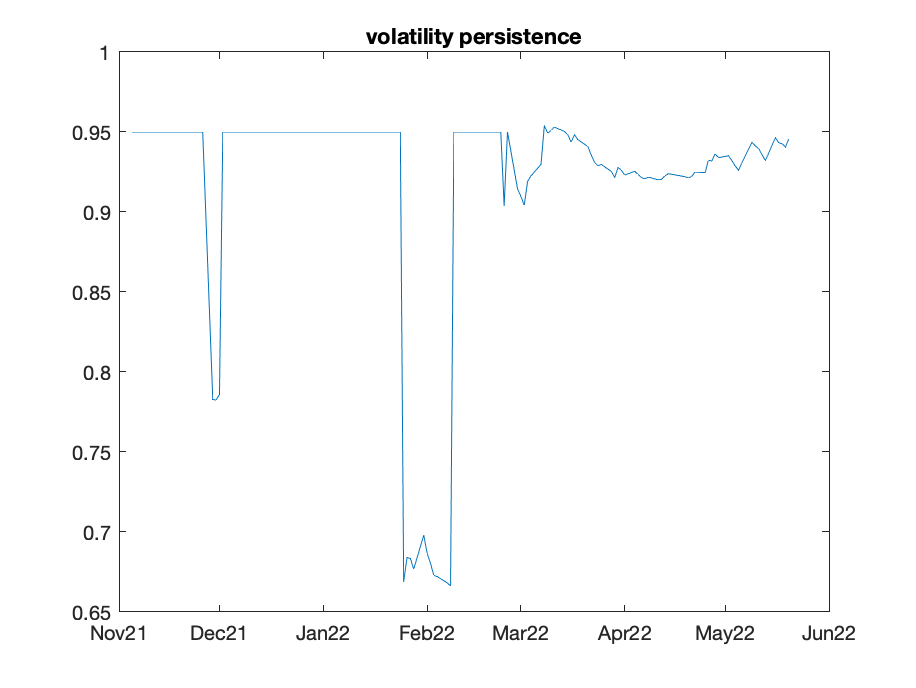

figure;
plot(Time_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_',Index,'_20220521'),"rv","vol_persis","Time_outsample","vf_GARCH", ...
    "vf_EGARCH","vf_GJRGARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_CPEGARCH","vf_CPEGARCHiteration","vf_CPGJRGARCH", ...
    "vf_CPGJRGARCHiteration","Ret_outsample");

## FTSE 200

Timeline=ftse.Date;
Time_outsample=ftse_rv_table.date;
logret=[0;price2ret(ftse.Price)];
rv=ftse_rv_table.rv;
Index='ftse';

Set empty matrices

index=(Timeline>=Time_outsample(1) & Timeline<=Time_outsample(end));
if sum(index)~=numel(Time_outsample)
    warning("Dates of daily prices and realised volatilities do not match.")
end

Ret_outsample=logret(index);
OutsampleStart=find(Timeline==Time_outsample(1));
n=numel(Time_outsample);

v_residuals=Ret_outsample.^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vol_persis=zeros(n,1);

Rolling windows forecast

for t=1:n
    ret=logret(OutsampleStart+t-1-252:OutsampleStart+t-1-1,:);

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(t)=forecast(EstMdl,1,ret);
    vol_persis(t)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    % CPGARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,1);
    K = OptimalClusterNumber(v_GARCH,LB);
    if K==numel(v_GARCH)
        K=K-1;
    end
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    vf_CPGARCH(t)=v_CPGARCH(end);

    % CPGARCH iteration
    v_CPGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGARCH);
    vf_CPGARCHiteration(t)=v_CPGARCHiteration(end);

    % EGARCH
    Mdl=egarch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(t)= forecast(EstMdl,1,ret);
    [LB,J,~]=Fisher_div_sqr(v_EGARCH,1);
    K = OptimalClusterNumber(v_EGARCH,LB);
    if K==numel(v_EGARCH)
        K=K-1;
    end
    [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    vf_CPEGARCH(t)=v_CPEGARCH(end);
    v_CPEGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPEGARCH);
    vf_CPEGARCHiteration(t)=v_CPEGARCHiteration(end);

    % GJR-GARCH
    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    vf_GJRGARCH(t)= forecast(EstMdl,1,ret);
    v_GJRGARCH = infer(EstMdl,ret);
    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,1);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    if K==numel(v_GJRGARCH)
        K=K-1;
    end
    [v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    vf_CPGJRGARCH(t)=v_CPGJRGARCH(end);
    v_CPGJRGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGJRGARCH);
    vf_CPGJRGARCHiteration(t)=v_CPGJRGARCHiteration(end);

    % RSGARCH
    addpath("m_Files_swgarch")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_RSGARCH(t)=datafcst.vH;
    rmpath("m_Files_swgarch")
end

## Results: 9 graphs with "log returns", "residual squares", "GARCH conditional variance", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "GJRGARCH forecast" and "RSGARCH forecast"

figure;
subplot(5,2,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,2,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,2,3);
v_GARCH=estimateGARCH(Ret_outsample,garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN));
line(Time_outsample,v_GARCH);
ylabel('GARCH Con.Var.');dateaxis("x",12);
subplot(5,2,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH forecast');dateaxis("x",12);
subplot(5,2,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH forecast');dateaxis("x",12);
subplot(5,2,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite. ');dateaxis("x",12);
subplot(5,2,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,2,8);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,2,9);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: 13 graphs with "log returns", "residual squares", "realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

figure;
subplot(5,3,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,3,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,3,3);
line(Time_outsample,rv);
ylabel('realised volatility')
subplot(5,3,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH');dateaxis("x",12);
subplot(5,3,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH');dateaxis("x",12);
subplot(5,3,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite.');dateaxis("x",12);
subplot(5,3,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,3,8);
line(Time_outsample,vf_CPEGARCH);
ylabel('CPEGARCH');dateaxis("x",12);
subplot(5,3,9);
line(Time_outsample,vf_CPEGARCHiteration);
ylabel('CPEGARCH Ite.');dateaxis("x",12);
subplot(5,3,10);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,3,11);
line(Time_outsample,vf_CPGJRGARCH);
ylabel('CPGJRGARCH');dateaxis("x",12);
subplot(5,3,12);
line(Time_outsample,vf_CPGJRGARCHiteration);
ylabel('CPGJRGARCH Ite.');dateaxis("x",12);
subplot(5,3,13);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast" and "CPGARCH iteration forecast"

figure;
col=rainbow(4);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:))
plot(Time_outsample,vf_CPGARCH, "Color",col(3,:))
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:))
legend("relisead volatility","GARCH","CPGARCH","GARCH iteration");

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

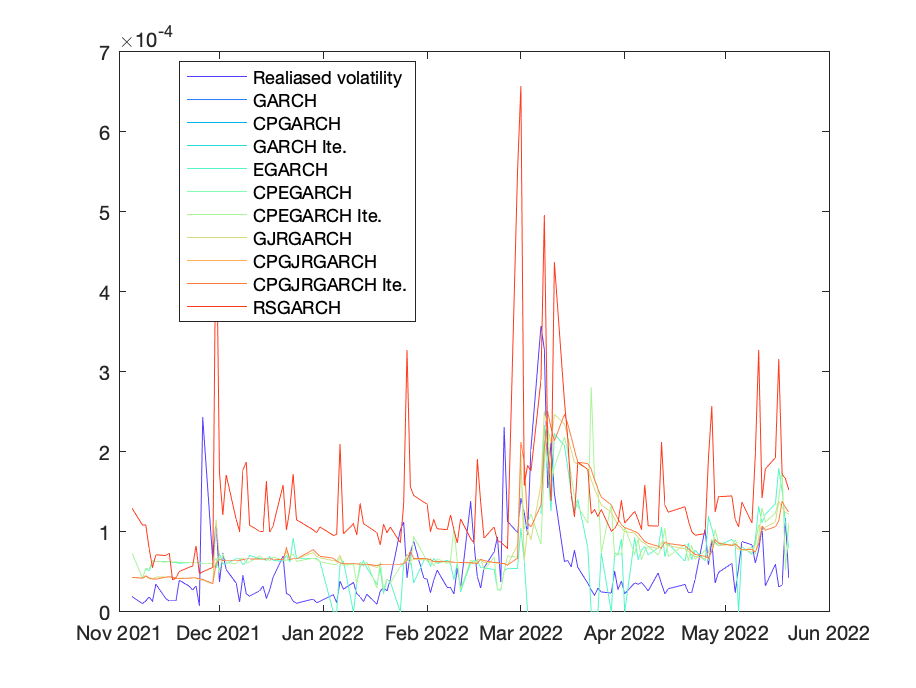

figure;
col=rainbow(11);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:));
plot(Time_outsample,vf_CPGARCH,"Color",col(3,:));
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:));
plot(Time_outsample,vf_EGARCH, "Color",col(5,:));
plot(Time_outsample,vf_CPEGARCH, "Color",col(6,:));
plot(Time_outsample,vf_CPEGARCHiteration, "Color",col(7,:));
plot(Time_outsample,vf_GJRGARCH, "Color",col(8,:));
plot(Time_outsample,vf_CPGJRGARCH,"Color",col(9,:));
plot(Time_outsample,vf_CPGJRGARCHiteration, "Color",col(10,:));
plot(Time_outsample,vf_RSGARCH, "Color",col(11,:));
legend("Realiased volatility","GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH","Location","best");

%legend("boxoff")

MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              4.8794e-05    6.3359e-05
    CPGARCH            5.0909e-05    6.6736e-05
    GARCH Ite.         5.0909e-05    6.6736e-05
    EGARCH                    Inf           Inf
    CPEGARCH                  Inf           Inf
    CPEGARCH Ite.      4.8623e-05    6.5613e-05
    GJRGARCH           4.8794e-05    6.3359e-05
    CPGJRGARCH         5.0909e-05    6.6736e-05
    CPGJRGARCH Ite.    5.0909e-05    6.6736e-05
    RSGARCH            9.7004e-05    0.00012298


## Test of actual forecast: 

## actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);

[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);

[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×3 table
                       low_bound    upper_bound       R2   
                       _________    ___________    ________

    GARCH               0.32028       0.70136       0.17452
    CPGARCH               0.244       0.61917       0.13473
    GARCH Ite.            0.244       0.61917       0.13473
    EGARCH                    0             0           NaN
    CPEGARCH                  0             0           NaN
    CPEGARCH Ite.       0.15864       0.59925      0.080067
    GJRGARCH            0.32028       0.70136       0.17452
    CPGJRGARCH            0.244       0.61917       0.13473
    CPGJRGARCH Ite.       0.244       0.61917       0.13473
    RSGARCH             0.16266       0.34947     

## Figure of volatility persistence

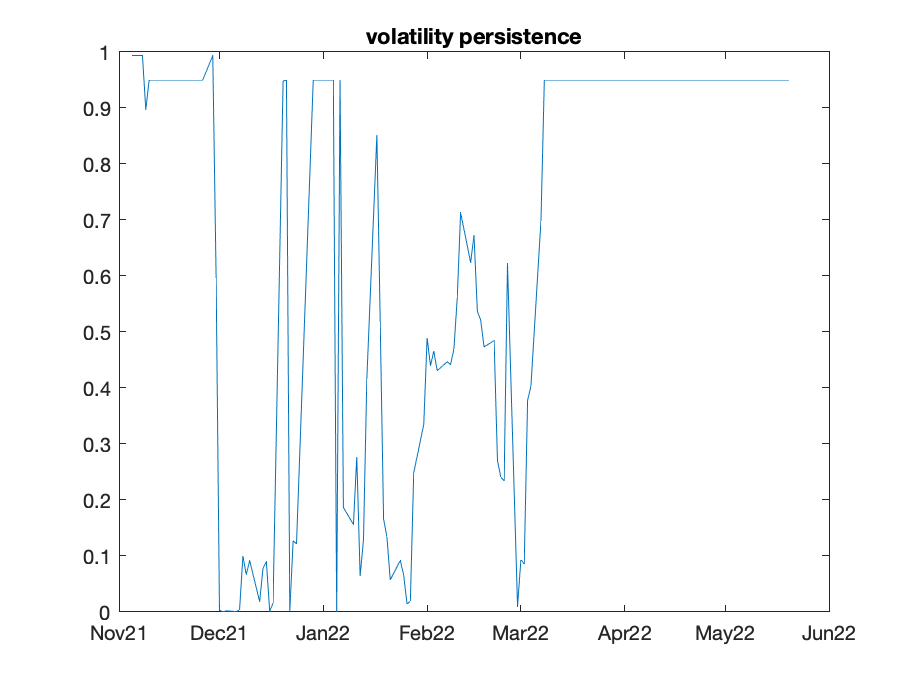

figure;
plot(Time_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_',Index,'_20220521'),"rv","vol_persis","Time_outsample","vf_GARCH", ...
    "vf_EGARCH","vf_GJRGARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_CPEGARCH","vf_CPEGARCHiteration","vf_CPGJRGARCH", ...
    "vf_CPGJRGARCHiteration","Ret_outsample");

## NIKKIE225

Timeline=nikkie.Date;
Time_outsample=nikkie_rv_table.date;
logret=[0;price2ret(nikkie.Price)];
rv=nikkie_rv_table.rv;
Index='nikkie';

Set empty matrices

index=(Timeline>=Time_outsample(1) & Timeline<=Time_outsample(end));
if sum(index)~=numel(Time_outsample)
    warning("Dates of daily prices and realised volatilities do not match.")
end

Ret_outsample=logret(index);
OutsampleStart=find(Timeline==Time_outsample(1));
n=numel(Time_outsample);

v_residuals=Ret_outsample.^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vol_persis=zeros(n,1);

Rolling windows forecast

for t=1:n
    ret=logret(OutsampleStart+t-1-252:OutsampleStart+t-1-1,:);

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(t)=forecast(EstMdl,1,ret);
    vol_persis(t)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    % CPGARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,1);
    K = OptimalClusterNumber(v_GARCH,LB);
    if K==numel(v_GARCH)
        K=K-1;
    end
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    vf_CPGARCH(t)=v_CPGARCH(end);

    % CPGARCH iteration
    v_CPGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGARCH);
    vf_CPGARCHiteration(t)=v_CPGARCHiteration(end);

    % EGARCH
    Mdl=egarch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(t)= forecast(EstMdl,1,ret);
    [LB,J,~]=Fisher_div_sqr(v_EGARCH,1);
    K = OptimalClusterNumber(v_EGARCH,LB);
    if K==numel(v_EGARCH)
        K=K-1;
    end
    [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    vf_CPEGARCH(t)=v_CPEGARCH(end);
    v_CPEGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPEGARCH);
    vf_CPEGARCHiteration(t)=v_CPEGARCHiteration(end);

    % GJR-GARCH
    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    vf_GJRGARCH(t)= forecast(EstMdl,1,ret);
    v_GJRGARCH = infer(EstMdl,ret);
    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,1);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    if K==numel(v_GJRGARCH)
        K=K-1;
    end
    [v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    vf_CPGJRGARCH(t)=v_CPGJRGARCH(end);
    v_CPGJRGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGJRGARCH);
    vf_CPGJRGARCHiteration(t)=v_CPGJRGARCHiteration(end);

    % RSGARCH
    addpath("m_Files_swgarch")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_RSGARCH(t)=datafcst.vH;
    rmpath("m_Files_swgarch")
end

## Results: 9 graphs with "log returns", "residual squares", "GARCH conditional variance", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "GJRGARCH forecast" and "RSGARCH forecast"

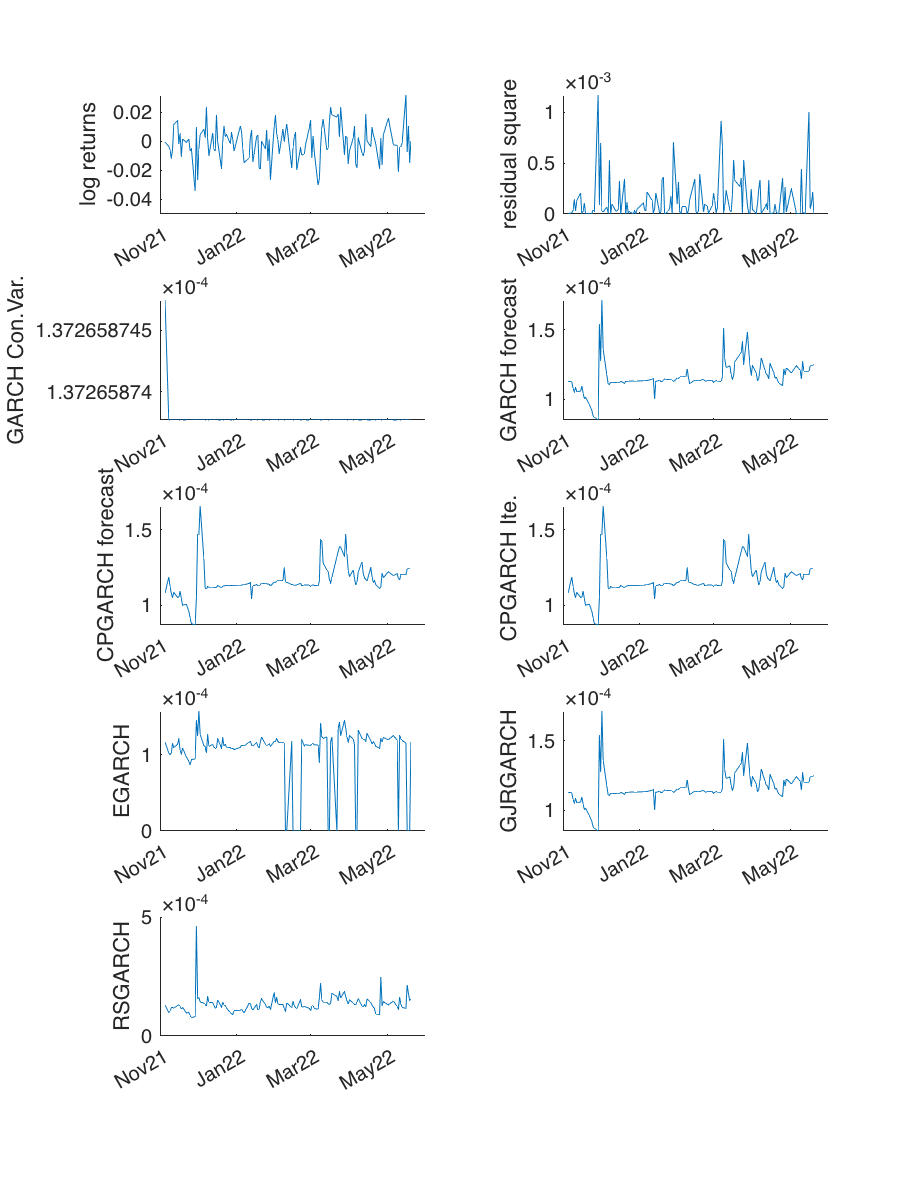

figure;
subplot(5,2,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,2,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,2,3);
v_GARCH=estimateGARCH(Ret_outsample,garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN));
line(Time_outsample,v_GARCH);
ylabel('GARCH Con.Var.');dateaxis("x",12);
subplot(5,2,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH forecast');dateaxis("x",12);
subplot(5,2,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH forecast');dateaxis("x",12);
subplot(5,2,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite. ');dateaxis("x",12);
subplot(5,2,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,2,8);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,2,9);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: 13 graphs with "log returns", "residual squares", "realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

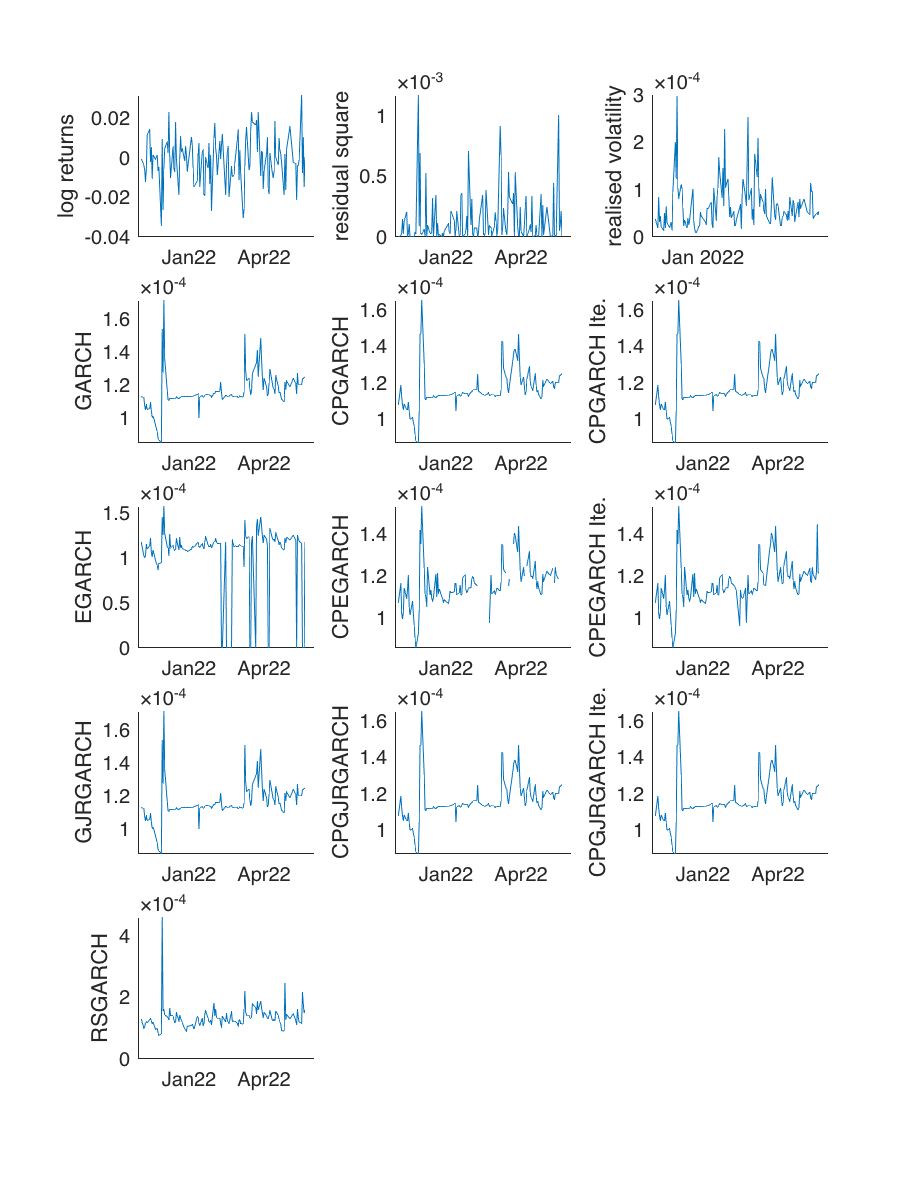

figure;
subplot(5,3,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,3,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,3,3);
line(Time_outsample,rv);
ylabel('realised volatility')
subplot(5,3,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH');dateaxis("x",12);
subplot(5,3,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH');dateaxis("x",12);
subplot(5,3,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite.');dateaxis("x",12);
subplot(5,3,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,3,8);
line(Time_outsample,vf_CPEGARCH);
ylabel('CPEGARCH');dateaxis("x",12);
subplot(5,3,9);
line(Time_outsample,vf_CPEGARCHiteration);
ylabel('CPEGARCH Ite.');dateaxis("x",12);
subplot(5,3,10);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,3,11);
line(Time_outsample,vf_CPGJRGARCH);
ylabel('CPGJRGARCH');dateaxis("x",12);
subplot(5,3,12);
line(Time_outsample,vf_CPGJRGARCHiteration);
ylabel('CPGJRGARCH Ite.');dateaxis("x",12);
subplot(5,3,13);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast" and "CPGARCH iteration forecast"

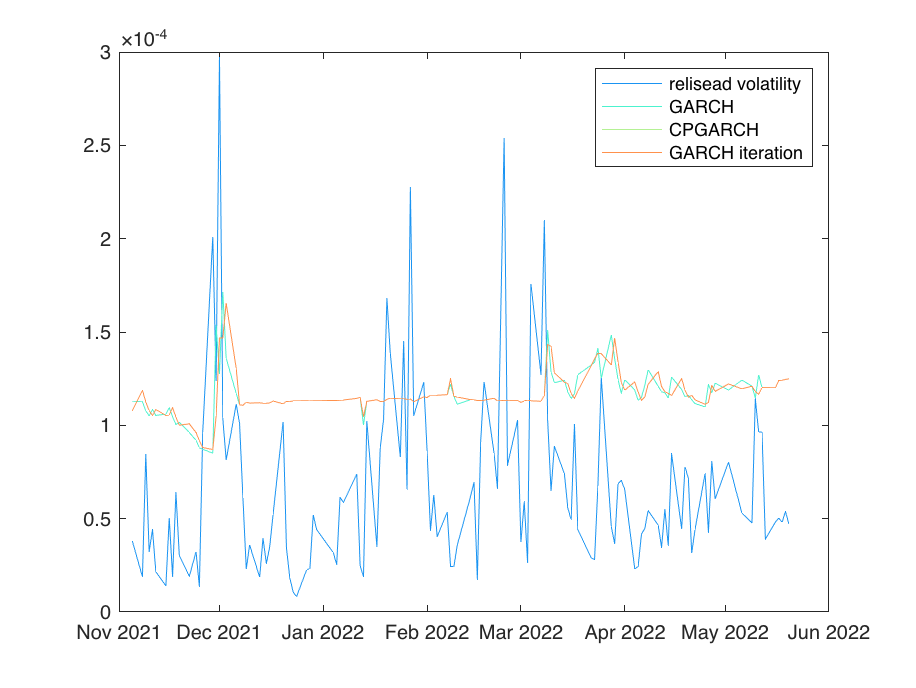

figure;
col=rainbow(4);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:))
plot(Time_outsample,vf_CPGARCH, "Color",col(3,:))
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:))
legend("relisead volatility","GARCH","CPGARCH","GARCH iteration");

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

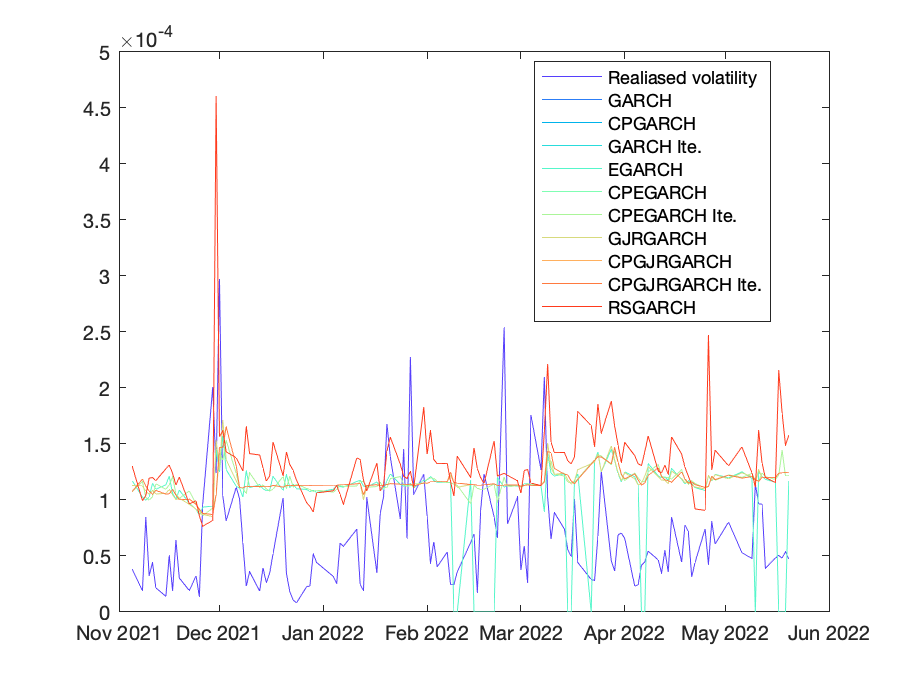

figure;
col=rainbow(11);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:));
plot(Time_outsample,vf_CPGARCH,"Color",col(3,:));
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:));
plot(Time_outsample,vf_EGARCH, "Color",col(5,:));
plot(Time_outsample,vf_CPEGARCH, "Color",col(6,:));
plot(Time_outsample,vf_CPEGARCHiteration, "Color",col(7,:));
plot(Time_outsample,vf_GJRGARCH, "Color",col(8,:));
plot(Time_outsample,vf_CPGJRGARCH,"Color",col(9,:));
plot(Time_outsample,vf_CPGJRGARCHiteration, "Color",col(10,:));
plot(Time_outsample,vf_RSGARCH, "Color",col(11,:));
legend("Realiased volatility","GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH","Location","best");

%legend("boxoff")

MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              6.2485e-05    6.9393e-05
    CPGARCH            6.2756e-05    6.9485e-05
    GARCH Ite.         6.2756e-05    6.9485e-05
    EGARCH             6.1974e-05    6.9454e-05
    CPEGARCH                  Inf           Inf
    CPEGARCH Ite.      6.2344e-05    6.9293e-05
    GJRGARCH           6.2485e-05    6.9393e-05
    CPGJRGARCH         6.2756e-05    6.9485e-05
    CPGJRGARCH Ite.    6.2756e-05    6.9485e-05
    RSGARCH            7.8408e-05    8.9374e-05


## Test of actual forecast: 

## actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);
[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);

[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×3 table
                       low_bound    upper_bound       R2    
                       _________    ___________    _________

    GARCH               -0.32301       1.1987       0.010028
    CPGARCH             -0.26926       1.3059       0.013074
    GARCH Ite.          -0.26926       1.3059       0.013074
    EGARCH              -0.12286      0.30683      0.0055756
    CPEGARCH                   0            0            NaN
    CPEGARCH Ite.       -0.33982       1.2868       0.010261
    GJRGARCH            -0.32301       1.1987       0.010028
    CPGJRGARCH          -0.26926       1.3059       0.013074
    CPGJRGARCH Ite.     -0.26926       1.3059       0.013074
    RSGARCH            -0.064707      0

## Figure of volatility persistence

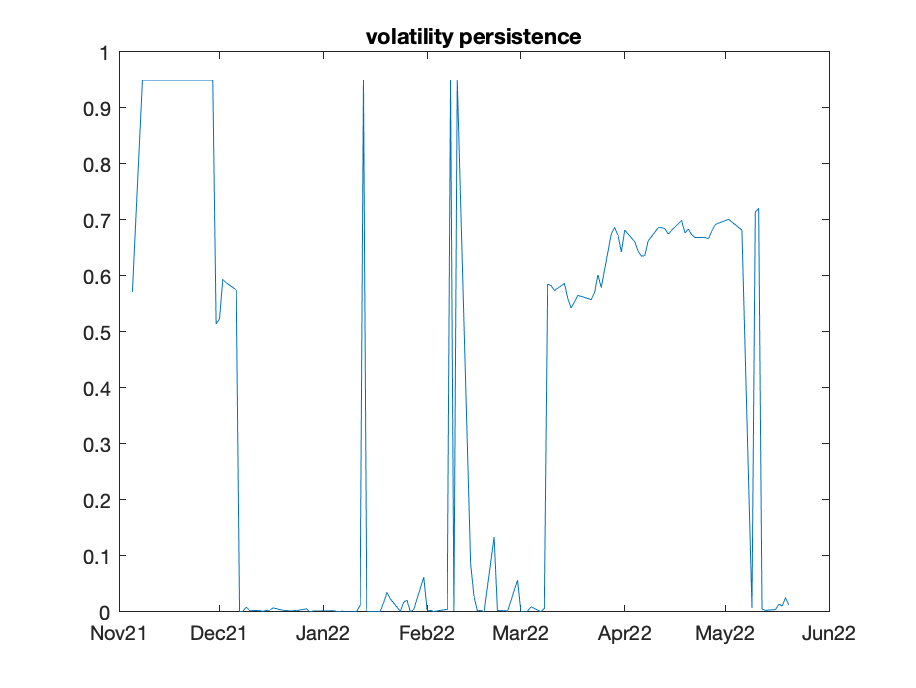

figure;
plot(Time_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_',Index,'_20220521'),"rv","vol_persis","Time_outsample","vf_GARCH", ...
    "vf_EGARCH","vf_GJRGARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_CPEGARCH","vf_CPEGARCHiteration","vf_CPGJRGARCH", ...
    "vf_CPGJRGARCHiteration","Ret_outsample");